## ESERCIZIO I: clustering gerarchico e componenti principali

% Caricare dentro MATLAB i dati della qualità della vita delle province
% Italiane (v. file benessere.xlsx presente nella sottocartella denominata
% capComponentiPrincipali della cartella matlabMfiles).
%
% Dopo aver opportunamente trasformato i dati costruire il dendrogramma
% utilizzando il metodo del legame medio. Visualizzare il dendrogramma
% aggiungendo i nomi delle righe. Mostrare nel dendrogramma prima tutte le
% aggregazioni e poi le ultime 70 aggregazioni (utilizzando l'opzione
% 'Orientation','left'). Tagliare il dendrogramma al valore soglia di
% distanza 3.5 e attribuire ogni unità (provincia) ad un determinato gruppo
%
% Costruire il vettore colonna di lunghezza n denominato idxAndRowLabels che
% contiene l'indicazione del gruppo di appartenenza insieme al nome della
% provincia.
% Ad esempio se la prima provincia Torino è assegnata al cluster 1 il primo
% elemento di idxAndRowLabels deve contenere  '3--Torino', se la seconda
% provincia Vercelli è assegnata al gruppo 3 il secondo elemento di
% idxAndRowLabels deve contenere  '3--Vercelli',
%
% La parte di seguito è dedicata all'interpretazione dei gruppi che sono
% stati ottenuti
%
% Calcolare e mostrare la distribuzione di frequenza dei gruppi che sono stati
% ottenuti. Commentare i gruppi ottenuti.
%
% Come si interpretano i gruppi formati da una sola unità? (se ci sono)
%
% Costruire la Table denominata CentroidiT (di dimensione kx(p+2) dove k è il numero di gruppi
% trovati) che contiene nella prima colonna l'indicazione del gruppo, nella seconda
% colonna le numerosità dei gruppi, nelle colonne 3:p+2 i centroidi
% dei gruppi che sono stati trovati
% Assegnare a questa table i nomi delle righe e delle colonne appropriati
% Osservazione: centroidi dei gruppi =matrice delle medie aritmetiche
% parziali riferite ai gruppi trovati.
% Mostrare tramite disp questa table
% Confrontare il gruppo 3 con il gruppo 6
%
% Estrarre dalla table CentroidiT in una variable denominata Centroidi
% la matrice di dimensione kxp di double contenente i centroidi
%
%
% Rappresentare graficamente i dati tramite un diagramma di dispersione in
% cui i punti presentano un colore che dipende dal gruppo di appartenenza
% (suggerimento: utilizzare la funzione gscatter) e aggiungere al grafico
% le etichette del gruppo di appartenenza e del nome della provincia.
% Aggiugnere al grafico i centroidi dei gruppi con riferimento alle
% variabili in esame.
%
% Costruire il diagramma di dispersione prima con riferimento alle
% variabili 1 e 2 poi alle variabili 3 e 4 e successivamente alle variabili
% 5 e 6. Aggiungere ad ogni diagramma i centroidi con colore rosso.
% Aggiungere in ogni scatter per ogni provincia il testo contenente il nome
% Interpretare i risultati ottenuti.

% Aggiungere due caselle a discesa in modo tale che quando si fa click sul
% pulsante Hide code appaia la schermata di seguito con la possibilità di
% selezionare le variabili da utilizzare per visualizzare il diagramma di
% dispersione insieme alle etichette delle province e dei relativi
% centroidi

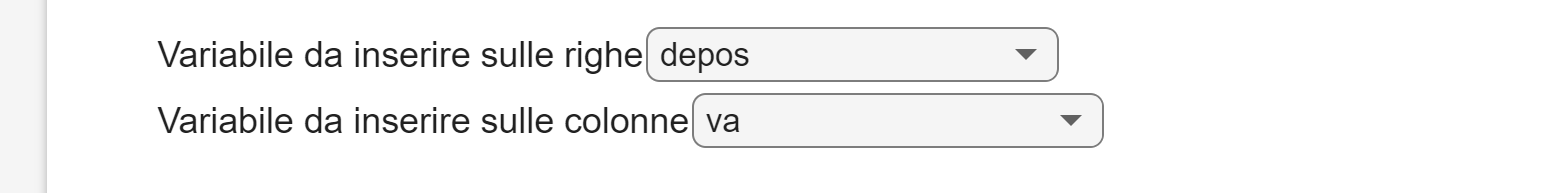

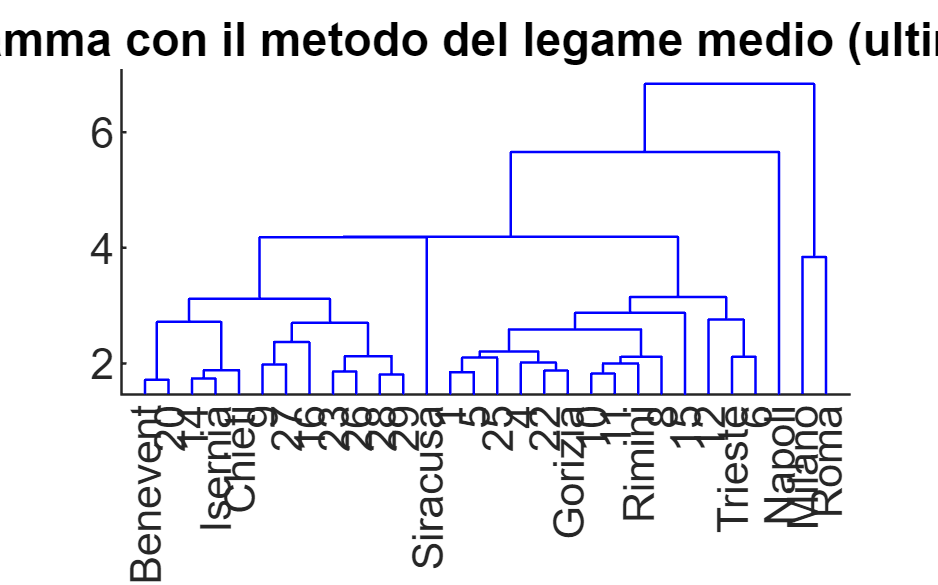

% Rappresentare i dati in termini di scatterplot matrix distinguendo per
% gruppo di appartenenza
%
% Rappresentare in coordinate parallele le province utilizzando
% un colore diverso in base al gruppo di appartenenza
% Rappresentare in coordinate parallele i centroidi
%
% Effettuare la trasformazione in termini di componenti principali non
% standardizzate (matrice ZV).
% Rappresentare gli scores (matrice ZV) delle prime due componenti
% principali con le etichette delle province e centroidi dei gruppi
% Osservazione: i centroidi dei gruppi devono essere proiettati nello
% spazio delle prime due componenti principali.
%
% Rappresentare gli score con gruppo
% di appartenenza + centroidi dei gruppi
%
% Rappresentare gli score con etichetta del nome della provincia e gruppo
% di appartenenza + centroidi dei gruppi


%% SOLUZIONE
% Il file benessere si trova nella sottocartella capComponentiPrincipali
% Osservazione il codice di seguito assume che ci si trovi dentro il percorso
% DataScienceWithMatlab\matlabMfiles\capClustering
% Il simbolo ..\ serve per tornare ad una cartella di livello superiore
% La sintassi
% "..\capComponentiPrincipali\benessere.xlsx"
% significa
% "vai alla cartella di livello superiore (nel nostro caso matlabMfiles e
% da questa scendi di un livello dentro la cartella denominata
% capComponentiPrincipali e punta al file benessere.xlsx"

% Osservazione: nei sistemi operativi Mac il separatore delle cartelle è lo
% slash "/" e non il backslash "\" di conseguenza occorre rimpiazzare \ con /. 
% La funzione di MATLAB filesep consente di trovare il separatore
% utilizzando dal sistema operativo in uso
separatore=filesep;

% La sintassi di seguito consente di caricare il file benessere.xlsx
% dalla cartella capComponentiPrincipali indipendentemente dal sistema
% operativo utilizzato
percorsofile= ['..' separatore 'capComponentiPrincipali' separatore 'benessere.xlsx'];
Xtable=readtable(percorsofile,'ReadRowNames',true);

% X = matrice di double senza nomi delle righe e nomi delle colonne
X=table2array(Xtable);

% varlabs = array of strings che contiene i nomi delle variabili
varlabs=string(Xtable.Properties.VariableNames);
% rowlabs = cell che contiene i nomi delle righe
rowlabs=Xtable.Properties.RowNames;

% Trasformazione in variabili standardizzate (matrice Z)
% La funzione zscore chiamata con 3 argomenti di output genera:
% 1) la matrice degli scostamenti standardizzati nel primo argomento di
% output
% 2) il vettore 1xp che contiene le medie aritmetiche delle p variabili
% originarie nel secondo argomento di output
% 3) il vettore 1xp che contiene gli scostamenti quadratici medi corretti
% delle p variabili originarie nel terzo argomento di output
[Z,mu,sigma]=zscore(X);

% Dopo aver opportunamente trasformato i dati costruire il dendrogramma
% utilizzando il metodo del legame medio. Visualizzare il dendrogramma
% aggiungendo i nomi delle righe. Mostrare nel dendrogramma prima tutte le
% aggregazioni e poi le ultime 70 aggregazioni (utilizzando l'opzione
% 'Orientation','left').

% Osservazione: questa volta l'input di linkage è la matrice dei dati
% (standardizzata)
out=linkage(Z,'average');
% vengono mostrate per default solo le ultime 30 aggregazioni
dendrogram(out,'labels',rowlabs);
title('Dendrogramma con il metodo del legame medio (ultime 30 aggr.)')

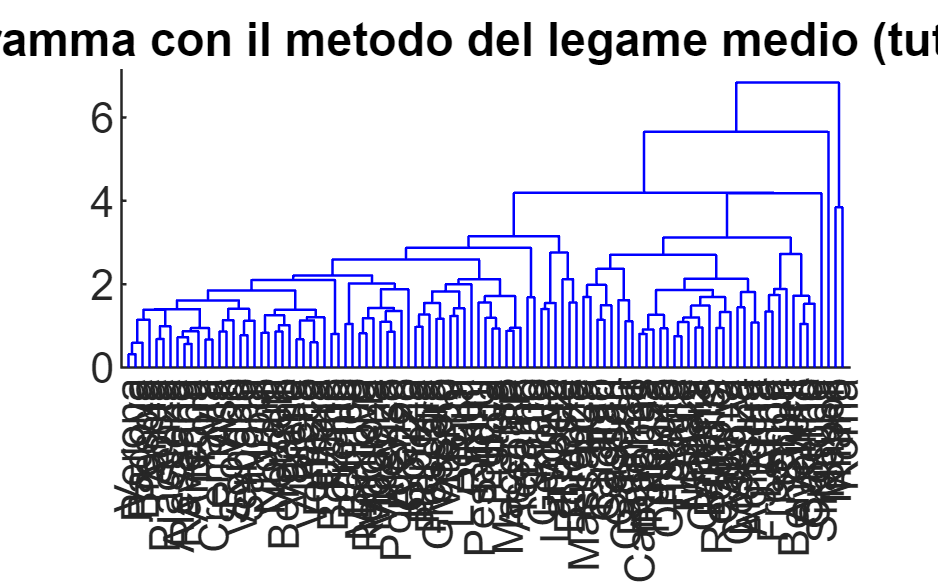


% Per mostrare tutte le aggregazioni
dendrogram(out,0,'labels',rowlabs);
title('Dendrogramma con il metodo del legame medio (tutte le aggr.)')

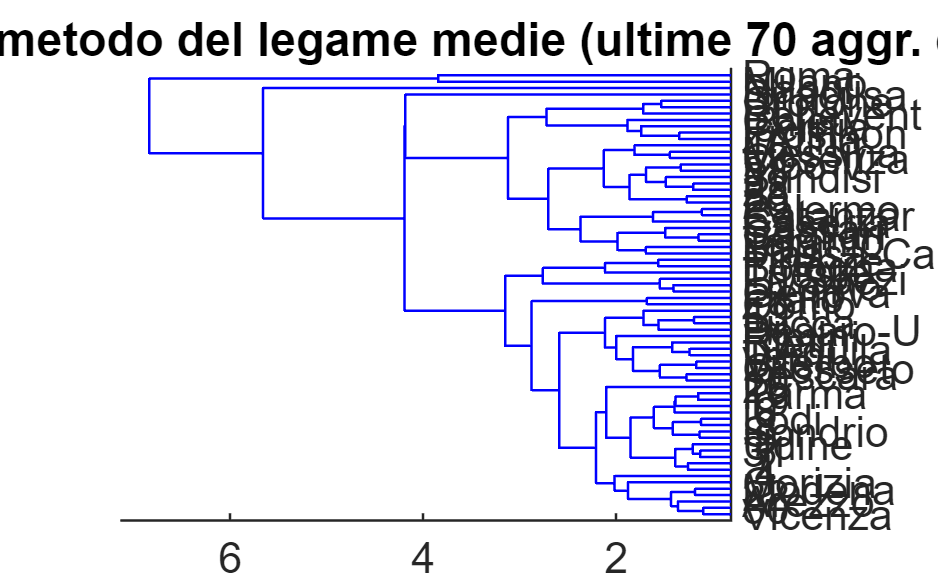


% Per mostrare solo le ultime 70 aggregazioni
dendrogram(out,70,'labels',rowlabs,'Orientation','left')
title('Dendrogramma con il metodo del legame medie (ultime 70 aggr. e orientamento sx)')

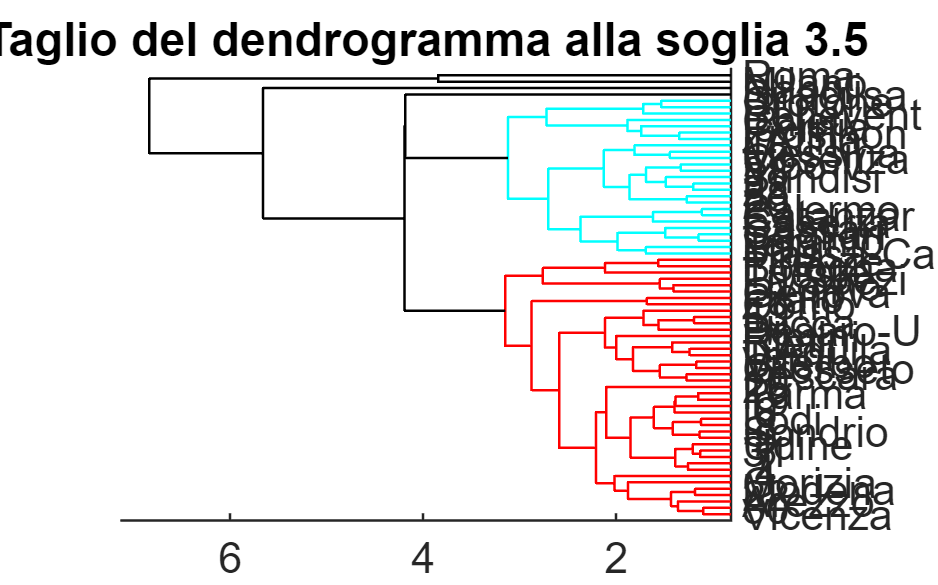


% Tagliare il dendrogramma al valore soglia di
% distanza 3.5
cutoff=3.5;
% Taglio del dendrogramma
dendrogram(out,70,'labels',rowlabs,'Orientation','left','ColorThreshold',3.5)
title('Taglio del dendrogramma alla soglia 3.5')


% Attribuire ogni unità (provincia) ad un determinato gruppo
idx=cluster(out,'cutoff',cutoff,'Criterion','distance');


% Costruire il vettore colonna di lunghezza n denominato idxAndRowLabels che
% contiene l'indicazione del gruppo di appartenenza insieme al nome della
% provincia.
% Ad esempio se la prima provincia Torino è assegnata al cluster 1 il primo
% elemento di idxAndRowLabels deve contenere  '3--Torino', se la seconda
% provincia Vercelli è assegnata al gruppo 3 il secondo elemento di
% idxAndRowLabels deve contenere  '3--Vercelli',
idxAndRowLabels=strcat(num2str(idx),'--',rowlabs);

% Calcolare la distribuzione di frequenza dei gruppi che sono stati
% ottenuti.
% Distribuzione di frequenze dei gruppi che sono stati trovati
disp('Distribuzione di frequenze dei gruppi')

Distribuzione di frequenze dei gruppi


disp(tabulate(idx))

    1.0000    1.0000    0.9709
    2.0000    1.0000    0.9709
    3.0000   65.0000   63.1068
    4.0000    1.0000    0.9709
    5.0000    1.0000    0.9709
    6.0000   34.0000   33.0097




% Come si interpretano i gruppi formati da una sola unità? (se ci sono)
% Commento: i gruppi 1, 2, 4 e 5 sono formati da una sola unità. Queste 4
% province sono da considerarsi valori anomali multivariati.

% Calcolo dei centroidi (medie artimetiche) per ogni gruppo

% Creo una nuova table denomianta Xtablewithidx.
% Questa una table ha 8 colonne. Le prime 7 colonne sono esattamente uguali
% a quelle della table originaria
% L'ultima colonna contiene il gruppo di appartenenza di ogni unità
Xtablewithidx=Xtable;
Xtablewithidx.idx=idx;


% Costruire la Table denominata CentroidiT (di dimensione kx(p+2) dove k è il numero di gruppi
% trovati) che contiene nella prima colonna l'indicazione del gruppo, nella seconda
% colonna le numerosità dei gruppi, nelle colonne 3:p+2 i centroidi
% dei gruppi che sono stati trovati
% Osservazione: centroidi dei gruppi =matrice delle medie aritmetiche
% parziali riferite ai gruppi trovati.
CentroidiT=grpstats(Xtablewithidx,'idx',{'mean'});

% Assegnare a questa table i nomi delle righe e delle colonne appropriati
nomiCentroidi={'Milano','Siracusa','Gruppo3','Napoli','Roma','Gruppo6'};
CentroidiT.Properties.RowNames=nomiCentroidi;

% Mostrare tramite disp questa table
disp('Table riassuntiva della numerosità dei gruppi e dei centroidi')

Table riassuntiva della numerosità dei gruppi e dei centroidi


disp(CentroidiT)

                idx    GroupCount    mean_va    mean_depos    mean_pensioni    mean_disocc    mean_export    mean_fallimen    mean_protesti
                ___    __________    _______    __________    _____________    ___________    ___________    _____________    _____________

    Milano       1          1         31050        20891          12826            5.22          32.63           54.24             77.6    
    Siracusa     2          1         12443       4408.6         9575.3           18.33          58.34           55.68            41.53    
    Gruppo3      3         65         20813       9033.6          10543          5

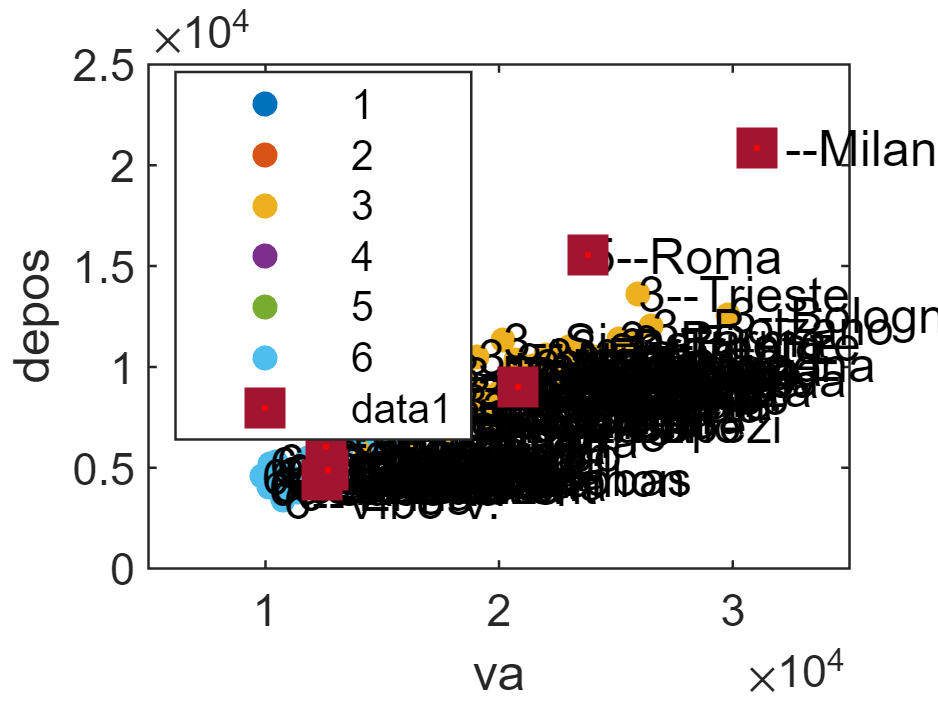


% Confrontare il gruppo 3 con il gruppo 6
% Commento: il gruppo 3 rispetto al gruppo 6 presenta valori dei centroidi SUPERIORI al
% gruppo 6 per le variabili va, depos, pensioni ed export.
% Al contrario il gruppo 3 rispetto al gruppo 6 presenta valori dei centroidi INFERIORI al
% gruppo 6 per le variabili disocc e protest.
% Le medie aritmetiche dei fallimenti sembrano simili

% Estrarre dalla table CentroidiT in una variable denominata Centroidi
% la matrice di dimensione kxp di double contenente i centroidi
Centroidi=CentroidiT{:,3:end};

% Interpretazione dei gruppi che sono stati trovati tramite i diagrammi di dispersione

% Costruire il diagramma di dispersione prima con riferimento alle
% variabili 1 e 2 poi alle variabili 3 e 4 e successivamente alle variabili
% 5 e 6. Aggiungere ad ogni diagramma i centroidi con colore rosso.
% Aggiungere in ogni scatter per ogni provincia il testo contenente il nome
% Interpretare i risultati ottenuti.

i=1;
j=2;
figure
gscatter(X(:,i),X(:,j),idx)
text(X(:,i),X(:,j),idxAndRowLabels)
xlabel(varlabs(i))
ylabel(varlabs(j))
hold('on')
% Aggiungo i centroidi
plot(Centroidi(:,i),Centroidi(:,j),'s','MarkerFaceColor','r','LineWidth',5)

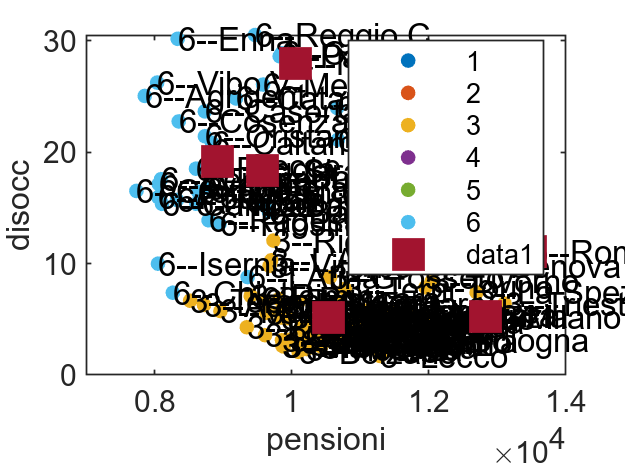

% Commento: il gruppo 6 è caratterizzato da valori di va e depos inferiori
% alla media. Roma presenta un indicatore dei depositi molto elevato dato il
% suo livello di valore aggiunto prodotto. Milano è una città con valori
% eccezionalmente elevati di va e depos


%% Plot variabili 3 e 4
figure
i=3;
j=4;
gscatter(X(:,i),X(:,j),idx)
text(X(:,i),X(:,j),idxAndRowLabels)
xlabel(varlabs(i))
ylabel(varlabs(j))
hold('on')
% Aggiungo i centroidi
plot(Centroidi(:,i),Centroidi(:,j),'s','MarkerFaceColor','r','LineWidth',5)

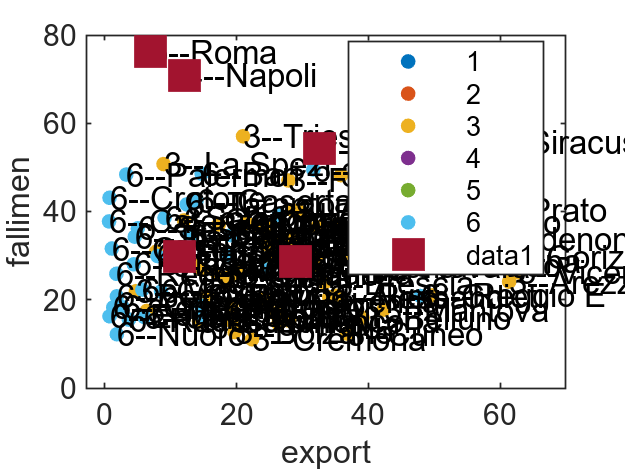


%% Plot variabili 5 e 6
figure
i=5;
j=6;
gscatter(X(:,i),X(:,j),idx)
text(X(:,i),X(:,j),idxAndRowLabels)
xlabel(varlabs(i))
ylabel(varlabs(j))
hold('on')
% Aggiungo i centroidi
plot(Centroidi(:,i),Centroidi(:,j),'s','MarkerFaceColor','r','LineWidth',5)

#### SCATTER DINAMICO TRAMITE CASELLE A DISCESA

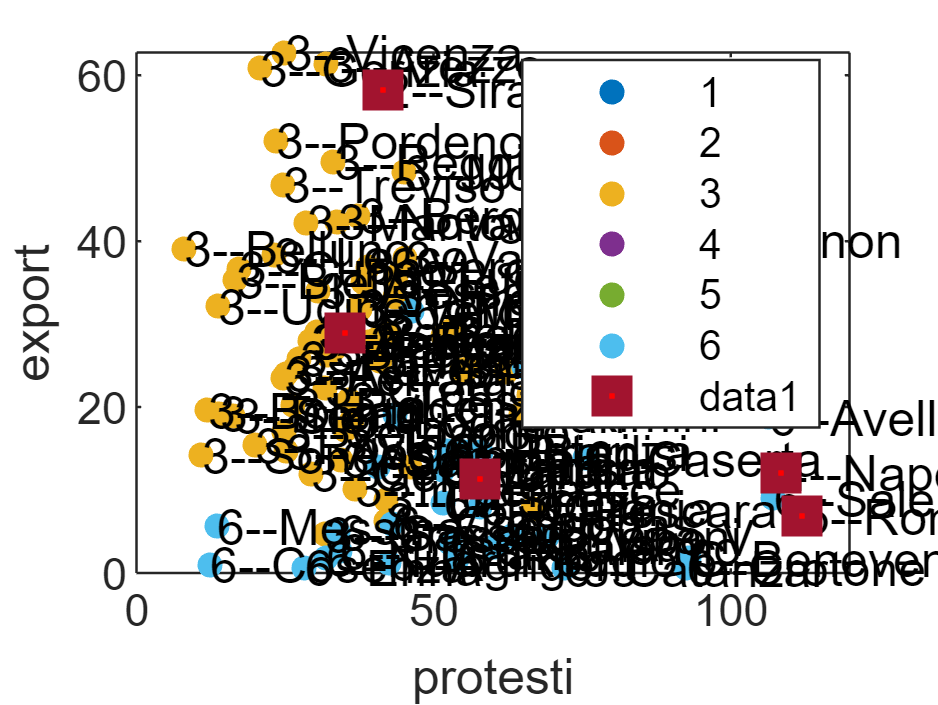

% Aggiungere due caselle a discesa in modo tale che quando si fa click sul
% pulsante Hide code appaia la schermata di seguito con la possibilità di
% selezionare le variabili da utilizzare per visualizzare il diagramma di
% dispersione insieme alle etichette delle province e dei relativi
% centroidi

figure

ilabel=varlabs(7);
jlabel=varlabs(5);
gscatter(Xtable{:,ilabel},Xtable{:,jlabel},idx)
text(Xtable{:,ilabel},Xtable{:,jlabel},idxAndRowLabels)
xlabel(ilabel)
ylabel(jlabel)
hold('on')
% Aggiungo i centroidi
plot(CentroidiT{:,'mean_'+ ilabel},CentroidiT{:,'mean_'+ jlabel},'s','MarkerFaceColor','r','LineWidth',5)

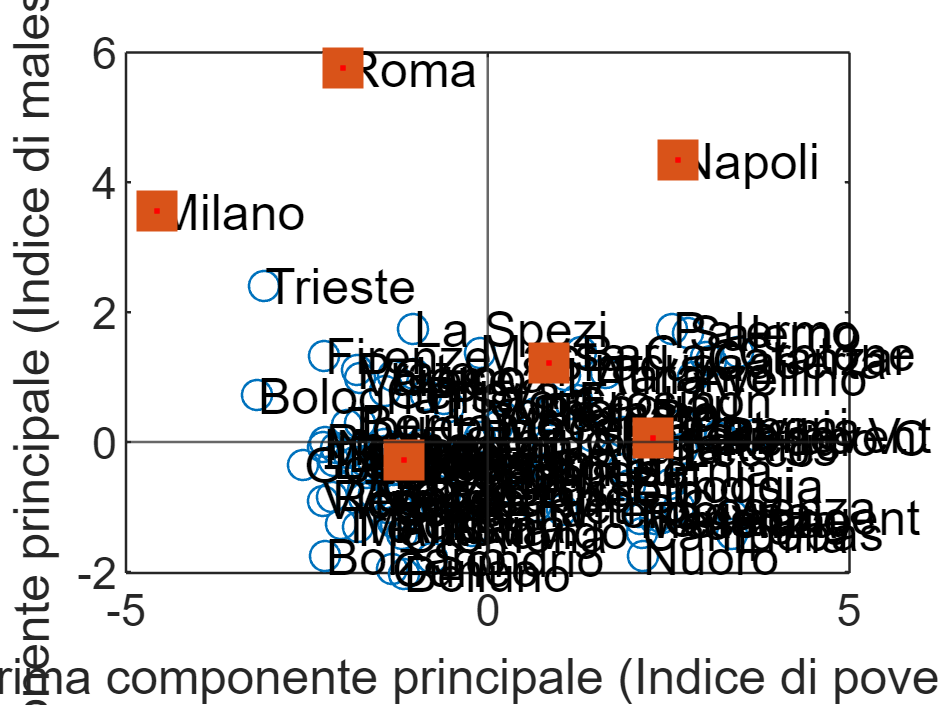


figure
%% Rappresentazione tramite spmplot
spmplot(Xtable,idx);


%% Rappresentazione in coordinate parallele delle variabili originarie con l'indicazoine 
% distinguendo per gruppo di appartenenza 
figure
hold('off')
parallelplot(Xtablewithidx,'GroupVariable','idx')

%% Rappresentazione in coordinate parallele dei centroidi
figure
parallelplot(CentroidiT(:,[1 3:end]));

%% Calcolo delle componenti principali e rappresentazione dei centroidi nello spazio delle prime due PC
PCAout=pcaFS(Xtable,'plots',0,'biplot',0,'dispresults',0);
% pcaFS viene chiamata con i name7value
% 'plots',0 per non mostrare i grafici 
% 'biplot',0 per non mostrare il biplot
% 'dispresults',0 per non mostrare i risultati sull'analisi in PC
% Estrazione degli scores Y=Z*V
Y=PCAout.score;


% Proietto i centroidi nello spazio delle prime due componenti principali
% In altri termini applico ai centroidi le stesse trasformazioni che ho
% applicato alla matrice X per ottenere le componenti principali
% ossia standardizzo moltiplico per i primi due autovettori
centroidiPCA=((Centroidi-mu)./sigma)*PCAout.coeff;

%% Rappresentazione degli score con etichette delle province e centroidi dei gruppi
close all
plot(Y(:,1),Y(:,2),'o')
xlabel('Prima componente principale (Indice di povertà)');
ylabel('Seconda componente principale (Indice di malessere delle aziende)');
text(Y(:,1),Y(:,2),rowlabs)
% Aggiungo l'asse x
yline(0)
% Aggiungo l'asse y
xline(0)

hold('on')
plot(centroidiPCA(:,1),centroidiPCA(:,2),'s','MarkerFaceColor','r','LineWidth',5)

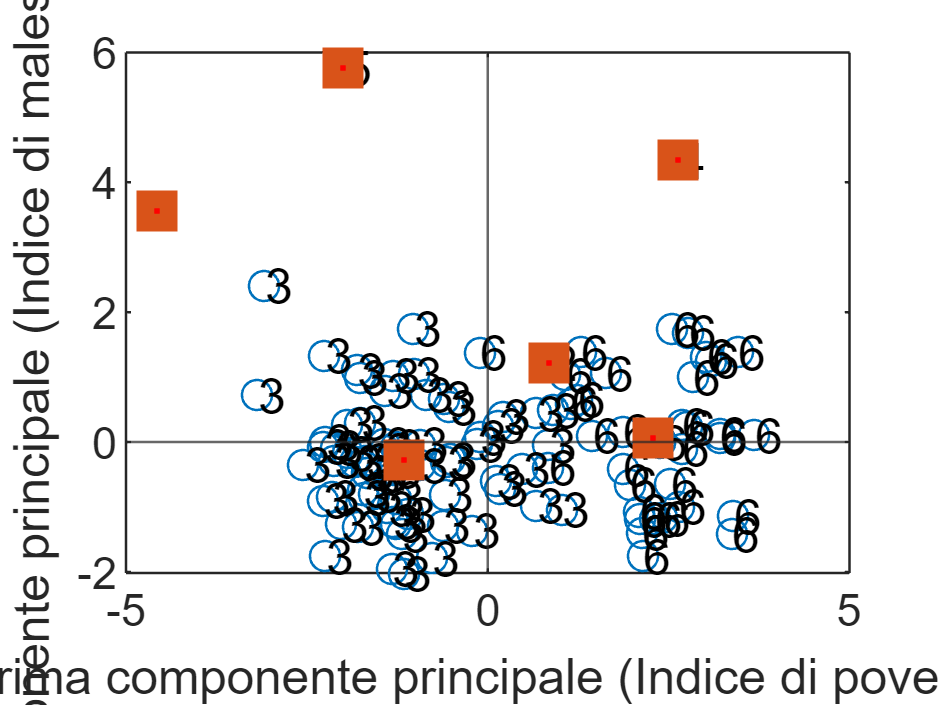



%% Rappresentazione degli score + centroidi + gruppo di appartenenza
figure
plot(Y(:,1),Y(:,2),'o')
xlabel('Prima componente principale (Indice di povertà)');
ylabel('Seconda componente principale (Indice di malessere delle aziende)');
text(Y(:,1),Y(:,2),num2str(idx))
% Aggiungo l'asse x
yline(0)
% Aggiungo l'asse y
xline(0)
hold('on')
plot(centroidiPCA(:,1),centroidiPCA(:,2),'s','MarkerFaceColor','r','LineWidth',5)

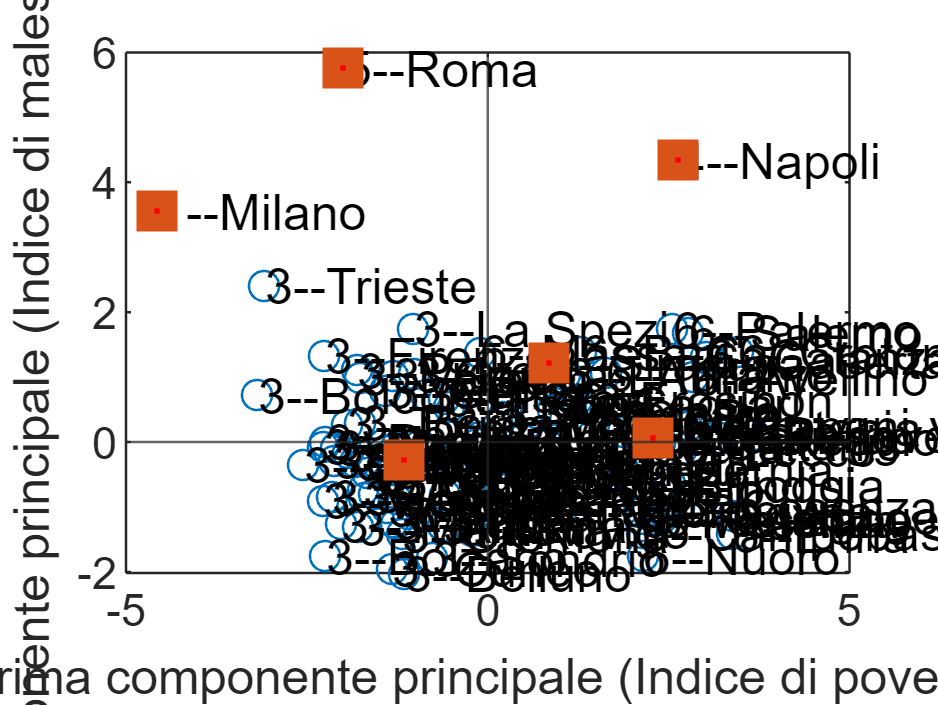

% Commento: il gruppo 6 è caratterizzato da valori molto elevati della
% prima componente principale (indice di povertà elevato)

%% Rappresentazione degli score + centroidi + (gruppi di appartenenzae etichetta provincia)
figure
plot(Y(:,1),Y(:,2),'o')
xlabel('Prima componente principale (Indice di povertà)');
ylabel('Seconda componente principale (Indice di malessere delle aziende)');
text(Y(:,1),Y(:,2),idxAndRowLabels)
% Aggiungo l'asse x
yline(0)
% Aggiungo l'asse y
xline(0)

hold('on')
plot(centroidiPCA(:,1),centroidiPCA(:,2),'s','MarkerFaceColor','r','LineWidth',5)

## ESERCIZIO II: riepilogo sul clustering (gerarchico e non gerarchico)

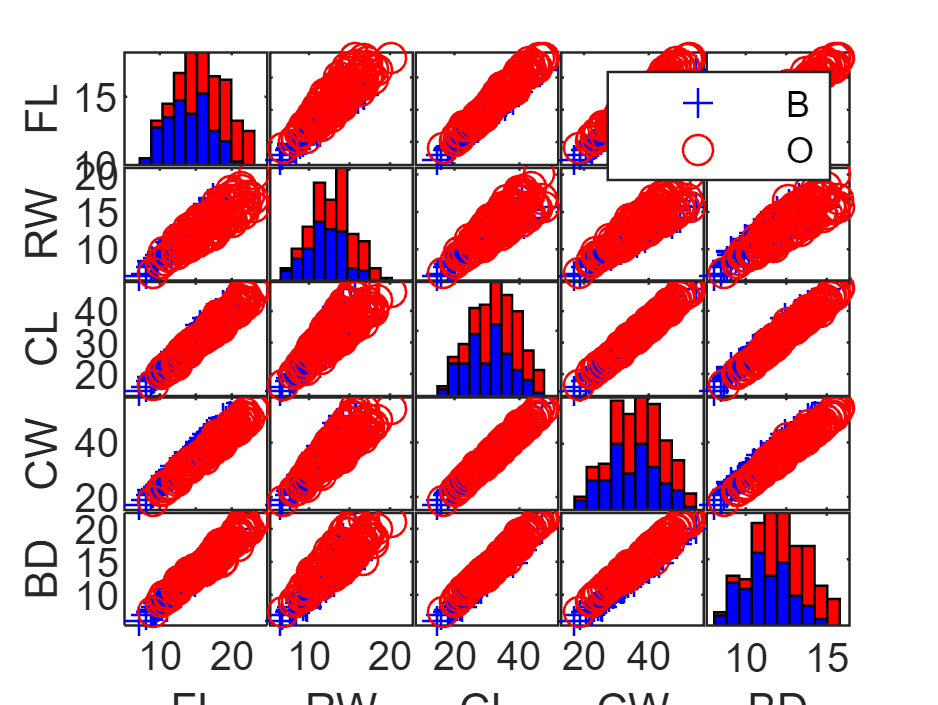

% Caricare in memoria il dataset  crabs (granchi) tramite l'istruzione
% load crabs.mat
% (attenzione si richiede che sia stata installato
% il toolbox FSDA versione >=8.5.3)
% Questo dataset contiene 200 righe e 8 colonne.
%
% La prima colonna è la specie dei granchi.
% La seconda il sesso, la terza l'indice di riga.
% Le rimanenti colonne descrivono 5 caratteristiche morfologiche
%
% Utilizzando la funzione spmplot costruire la matrice dei diagrammi di
% dispersione delle 5 caratteristiche morfologiche, distinguendo le unità
% per specie.
% Commentare la matrice dei diagrammi di dispersione.


% Applicare alle 5 caratteristiche morfologiche
%
% 1) la metodologia di cluster gerarchico del legame singolo,
% Costuire il dendrogramma. Effettuare il taglio del dendrogramma
% utilizzando la soglia di distanza 1.8. Assegnare ogni unità ad un
% gruppo. Commentare i gruppi che sono stati trovati ed il loro
% significato (se esiste).
%
% 2) la metodologia di cluster gerarchico del legame medio. Mostrare il
% dendrogramma visualizzando tutte le aggregazione con l'opzione
% 'Orientation','right'. Colorare nel dendrogramma i rami utilizzando la
% 'ColorThreshold' di default. Quanti gruppi questa metodologia suggerisce
% se si utilizza la 'ColorThreshold' di default? Utilizzando il numero di
% gruppi suggerito dalla 'ColorThreshold' di default, assegnare ogni unità
% ad un determinato gruppo. Utilizzando la funzione spmplot, commentare ed
% interpretare i gruppi che vengono ottenuti. Illustrare se i gruppi
% trovati corrispondono alla suddivisione dei granchi nelle due specie.
% Calcolare l'indice di Rand aggiustato tra la specie la classificazione
% ottenuta. Commentare l'indice di Rand.
%
% 3) la metodologia delle k medie adattando come numero di gruppi k=2.
% Commentare i risultati ottenuti. Illustrare se i due gruppi trovati
% corrispondono alla suddivisione dei granchi nelle due specie.
% Utilizzando la funzione evalcluster determinare il numero ottimo di
% gruppi tramite il criterio di Calinski e Harabaz. Come valore di k da
% investigare scegliere 1,2, ..., 9.
% Mostrare la matrice dei diagrammi di dispersione utilizzando come
% variabile di raggruppamento l'assegnazione ai diversi gruppi
% Calcolare l'indice di Rand aggiustato tra la specie la classificazione
% ottenuta. Commentare l'indice di Rand.

% 4) la metodologia di tclust utilizzando come numero di gruppi k=2, un
% livello di trimming pari a 0.05 (terzo argomento di input) ed imponendo
% il vincolo che il rapporto tra il massimo e il minimo autovalore delle
% matrici di covarianze non sia superiore a 1000 (quarto argomento di
% input). Calcolare l'indice di Rand aggiustato tra la specie la
% classificazione ottenuta. Commentare l'indice di Rand.


% Caricamento dati e matrice dei diagrammi di dispersione tra le 5
% variabili morfologiche, utilizzando come variabile di raggruppamento la
% specie di appartenenza.
load crabs.mat;
spmplot(crabs(:,4:end),crabs.sp);

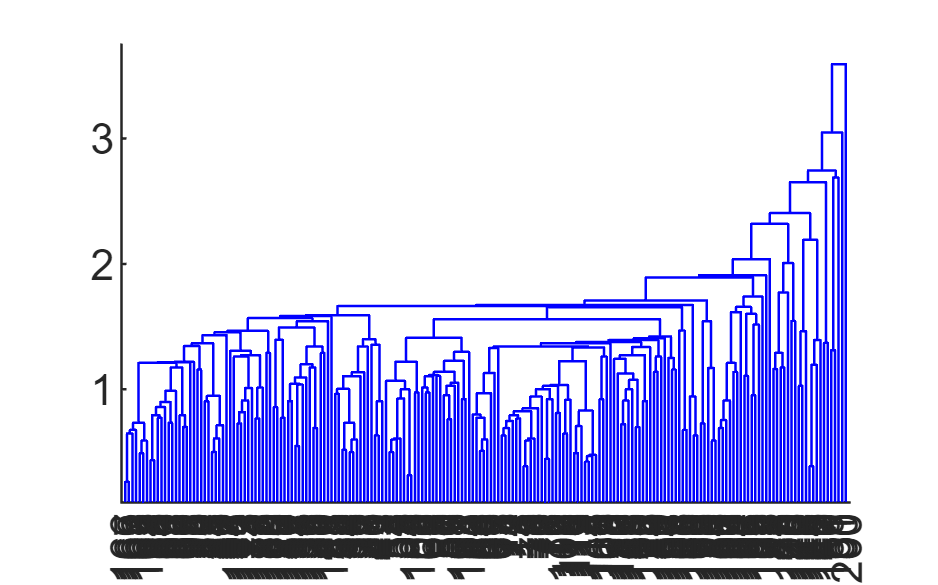


% La matrice dei diagrammi di dispersione rileva che le 5 caratteristiche
% morfologiche presentano una correlazione molto forte

% X = Matrice dei dati di dimensione 200x5 in formato double
X=crabs{:,4:end};

% Applicare alle 5 caratteristiche morfologiche
%
% 1) la metodologia di cluster gerarchico del legame singolo,
% Costuire il dendrogramma. Effettuare il taglio del dendrogramma
% utilizzando la soglia di distanza 1.8. Assegnare ogni unità ad un
% gruppo. Commentare i gruppi che sono stati trovati ed il loro
% significato (se esiste).

% Cluster gerarchico con il metodo del legame singolo
tree = linkage(X);

% Creazione del dendrogramma
% Il secondo argomento pari a 0
% specifica di mostrare tutti i nodi
dendrogram(tree,0)

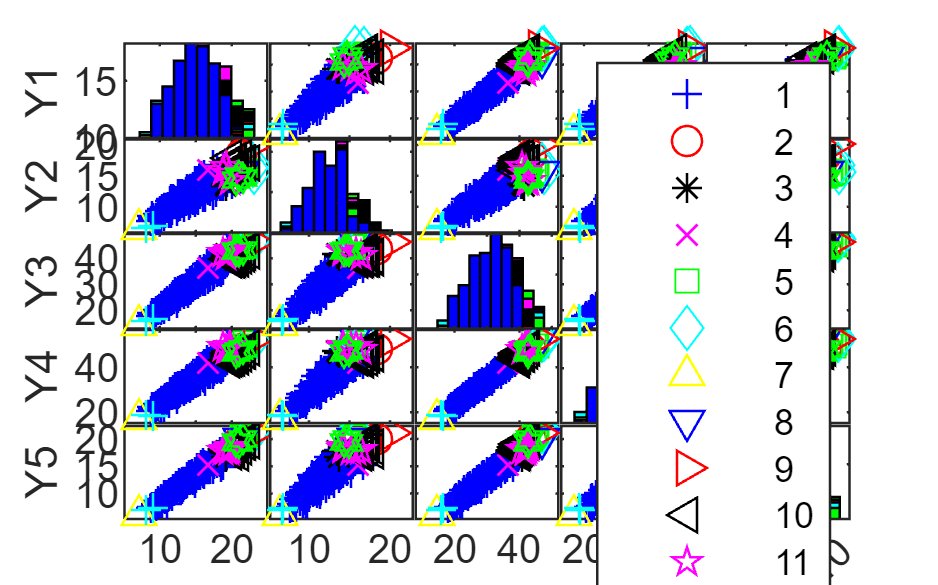



% Taglio del dendrogramma  alla soglia di distanza 1.8
groupLS = cluster(tree,'cutoff',1.8,'Criterion','distance');

% Commentare i gruppi che sono stati trovati ed il loro
% significato (se esiste).

% spmplot di FSDA per visualizzare i gruppi ottenuti
spmplot(X,groupLS);

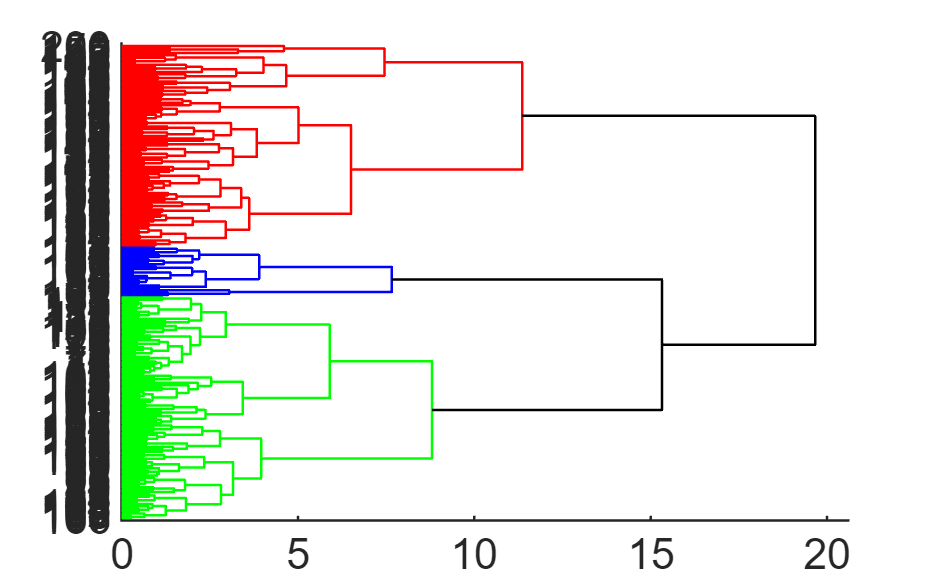

% Commento: il metodo del legame singolo in questo esempio fallisce
% miseramente.
% Sono stati trovati 13 gruppi. Un gruppo contiene oltre l'80% dei granchi.
% Gli altri gruppi sono composti da poche unità e non hanno la minima
% interpretazione.

% 2) la metodologia di cluster gerarchico del legame medio. Mostrare il
% dendrogramma visualizzando tutte le aggregazione con l'opzione
% 'Orientation','right'. Colorare nel dendrogramma i rami utilizzando la
% 'ColorThreshold' di default. 


% Metodo del legame medio
tree = linkage(X,'average');
% Motrare il dendrogramma visualizzando tutte le aggregazione
% con l'opzione 'Orientation','right'.
% Colorare nel dendrogramma i rami utilizzando la 'ColorThreshold' di default
dendrogram(tree,0,'Orientation','right','ColorThreshold','default');

% Quanti gruppi questa metodologia suggerisce
% se si utilizza la 'ColorThreshold' di default? 

% Se si utilizza la 'ColorThreshold' di default questa metodologia
% suggerisce la presenza di tre gruppi

% Utilizzando il numero di
% gruppi suggerito dalla 'ColorThreshold' di default, assegnare ogni unità
% ad un determinato gruppo. 

% La funzione cluster viene chiamata con il name/value MaxClust',3 per
% utilizzare 3 gruppi
groupLM = cluster(tree,'MaxClust',3);
tabulate(groupLM)

  Value    Count   Percent
      1       21     10.50%
      2       94     47.00%
      3       85     42.50%


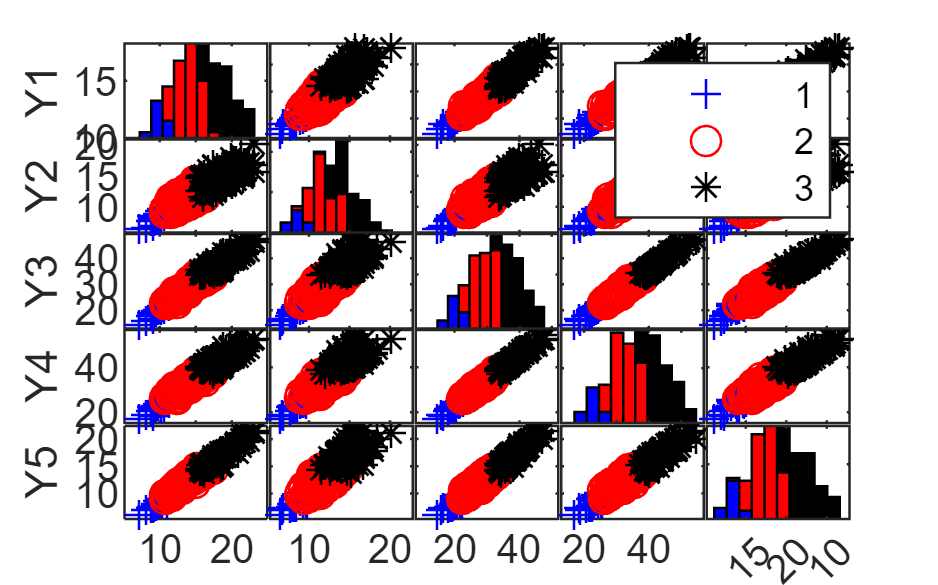

% Utilizzando la funzione spmplot, commentare ed
% interpretare i gruppi che vengono ottenuti. 

% Commentare i gruppi che vengono ottenuti.
spmplot(X,groupLM);

% Distribuzione di frequenza delle unità che appartengono ai diversi gruppi
tabulate(groupLM)

  Value    Count   Percent
      1       21     10.50%
      2       94     47.00%
      3       85     42.50%


% Illustrare se i gruppi
% trovati corrispondono alla suddivisione dei granchi nelle due specie.

% La matrice dei diagrammi di dispersione suggerische che il gruppo formato
% da circa il 10 per cento delle unità presenta caratteristiche
% morfologiche inferiori alla media per ognuna delle 5 variabili. Il gruppo
% che contiene il 42 per cento delle unità presenta caratteristiche
% morfologiche superiori alla media per ognuna delle 5 variabili.
% Anche in questo caso le due specie di granchio sono distribuite tra i 3
% gruppi trovati.
rindexgroupLM=RandIndexFS(groupLM,crabs.sp)

rindexgroupLM = 0.0346

disp('Indice di Rand aggiustato tra la specie e la partizione derivante dall''applicazione del legame medio')

Indice di Rand aggiustato tra la specie e la partizione derivante dall'applicazione del legame medio


disp(rindexgroupLM)

    0.0346



% Calcolare l'indice di Rand aggiustato tra la specie la classificazione
% ottenuta. Commentare l'indice di Rand.
% Commento: l'indice di Rand segnala che i gruppi trovati non corrispondono
% per niente alla classificazione nelle due specie

% 3) la metodologia delle k medie adattando come numero di gruppi k=2.
% Commentare i risultati ottenuti. 

% Metodologia delle k medie con k=2
[groupKM]=kmeans(X,2,"Replicates",100);
spmplot(X,groupKM);
% Illustrare se i due gruppi trovati
% corrispondono alla suddivisione dei granchi nelle due specie.
% Mostrare la matrice dei diagrammi di dispersione utilizzando come
% variabile di gruppi l'assegnazione ai diversi gruppi
% Calcolare l'indice di Rand aggiustato tra la specie la classificazione
% ottenuta. Commentare l'indice di Rand.

% Commento: il metodo delle k medie tende a trovare gruppi di forma
% prevalentemente sferica. Il primo gruppo è caratterizzato da granchi che
% presentano valori generalmente inferiori alla medie delle 5
% caratteristice morfologiche il secondo gruppo è caratterizzato da granchi che
% presentano valori generalmente superiori alla media delle 5
% caratteristice morfologiche. I 2 gruppi trovati non consentono in alcun
% modo di distinguere tra le due tipologie di granchio.
rindexgropKM=RandIndexFS(groupKM,crabs.sp)
disp('Indice di Rand aggiustato tra la specie e la partizione derivante dall''applicazione di kmeans con k=2')
disp(rindexgropKM)
% Anche in questo caso le due specie di granchio sono distribuite tra i
% gruppi che sono stati trovati


% Utilizzando la funzione evalcluster determinare il numero ottimo di
% gruppi tramite il criterio di Calinski e Harabaz.

figure
eva = evalclusters(X,'kmeans','CalinskiHarabasz','KList',1:9);
plot(eva);
% Questo grafico mostra chiaramente che il numero ottimo dei gruppi è pari
% a 7 oppure 8
% Osservazione: il grafico precedente può variare di volta in volta.
% In alcuni casi il massimo è pari a 7 in altri è pari ad 8.

% Distribuzione di frequenza dei gruppi che sono stati ottenuti
gropKMopt=eva.OptimalY;
tabulate(gropKMopt)
spmplot(X,gropKMopt);
% I gruppi trovati presentano una forma sferica e presentano caratterische
% via via crescenti delle 5 variabili in esame.
% Ancora una volta i gruppi trovati non consentono in alcun
% modo di distinguere tra granchi delle due specie.
rindexgropKMopt=RandIndexFS(gropKMopt,crabs.sp)
disp('Indice di Rand aggiustato tra la specie e il numero ottimo di gruppi utilizzando kmeans')
disp(rindexgropKMopt)
% 4) la metodologia di tclust utilizzando come numero di gruppi k=2, un
% livello di trimming pari a 0.05 (terzo argomento di input) ed imponendo
% il vincolo che il rapporto tra il massimo e il minimo autovalore delle
% matrici di covarianze non sia superiore a 1000 (quarto argomento di
% input). Calcolare l'indice di Rand aggiustato tra la specie la
% classificazione ottenuta. Commentare l'indice di Rand.


% Osservazione per trovare gruppi di forma ellittica è necessario fare
% riferimento a metotologie che utilizzano non le distanze euclidee ma le
% distanze di Mahalanobis.
idxTC=tclust(X,2,0.05,1000,'plots',1);

% Calcolare l'indice di Rand tra la partizione ottenuta tramite
% l'applicazione dei tclust e la specie.

rindexTCLUST=RandIndexFS(idxTC.idx,crabs.sp)
disp('Indice di Rand aggiustato tra la specie e l''ouptut di tclust')
disp(rindexTCLUST)
% L'accostamento è vicino al 90 per cento circa. I due gruppi trovati
% corrispondono alle due specie.
